clear all
close all
clc

rng(1);

load('Benchmark_EEG_small')


Preprocessing Data

partici = 4    %Choose participant

partici = 4

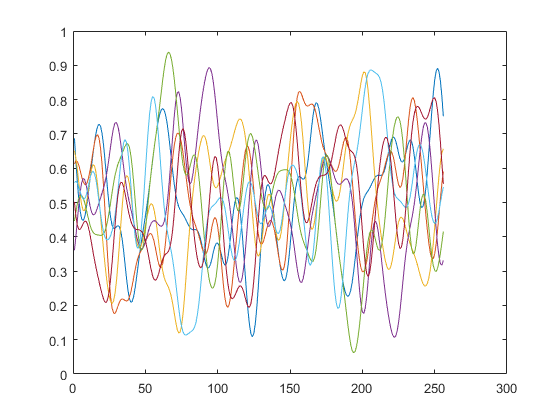


input = squeeze(data.u(partici,:,:))' /6+0.5 ;
output = squeeze(data.y(partici,:,:))'/8+0.5 ;

plot(input)

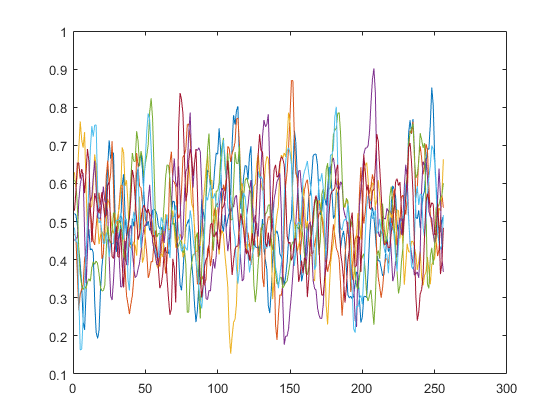

plot(output)


% histogram(input);
% histogram(output);


Choose lags

%angle
inlags=[10 9 8 6 5 4];
for l = 1:length(inlags)
u(:,l) = (reshape(input(end-inlags(l)-241:end-inlags(l)-1,:), [],1));
end

%angular velocity
vlags=[4 5 6];
for l = 1:length(vlags)
v(:,l) = (reshape(input(end-vlags(l)-241:end-vlags(l)-1,:), [],1) - reshape(input(end-vlags(l)-240:end-vlags(l),:), [],1))/0.2+0.5;
end

% plot(v)

%output
outlags=[0 1 2 3 4 5];
for l = 1:length(outlags)
y(:,l) = reshape(output(end-outlags(l)-240:end-outlags(l),:), [],1);
end


Split test and training set

for period = 1:7;
testind = (241*(period-1)+1):241*period;

trainind = setdiff([1:size(u,1)],testind);

featurez = [y(trainind,2:end)  v(trainind,:) u(trainind,:)];
zeta = y(trainind,1);

tfeaturez = [y(testind,2:end)  v(testind,:) u(testind,:)];
yt = y(testind,1);



% histogram(featurez(:,1),100)
% 
% inters = 0:0.005:0.995;
% for s = 1:200
% groupz{s} = (featurez(:,1)>= inters(s) & featurez(:,1)< inters(s)+0.005);
% end
% 
% sampled = [];
% sampledzeta= [];
% for s = 1:200
%     if ~isempty(featurez(groupz{s},:))      
% [sam,idx] = datasample(featurez(groupz{s},:),40,1);
% sampled = [sampled ; sam];
% zet = zeta(groupz{s});
% sampledzeta =  [sampledzeta ; zet(idx')];
%     end
% end
% 
% 
% histogram(sampled(:,1),200);
% histogram(sampledzeta(:,1),200);

% 
% featurez = sampled;
% zeta = sampledzeta;


Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 3;                 %degree B-spline
m = 1;                  %Number of knot intervals
In = n+m;               %Number of B-splines

un = basisvectors(featurez,n,m);




Initialize tensor train

% Choose TT-ranks
maxrank = 5;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 4.4405e-06


Compression: 4.4405e-06


Compression: 4.4405e-06


Compression: 4.4405e-06


Compression: 4.4405e-06


Compression: 4.4405e-06


Compression: 4.4405e-06


Optimize TT cores

lambda=1*10^-9 ;
gamma=0 ;
% gamma=;

difforder=2;
MAXITR = 4*d;

rez = [];
% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);


% MAXITR = d;
nselect = ones([1,MAXITR])*N;
% plot(nselect)

[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,gamma,difforder);
rez = [rez res1];

% 
% plot(res1)
% plot(res2)
% 
% trainerror = res1(end)
% 
% plot(rez)

Evaluate Test data


% yhattrain  = evalspline(TN,featurez,n,m);
% 
% figure;
% hold on
% plot(zeta)
% plot(yhattrain)
% hold off
% axis([0 256 -inf inf]);
% 
% erboiz = (yhattrain-zeta);
% VAF = 1-var(erboiz)/var(zeta)
% MSE = immse(yhattrain,zeta)


yhat = evalspline(TN,tfeaturez,n,m);


erboi = (yhat-yt);
% histogram((erboi)');
VAF1(period) = 1-var(erboi)/var(yt)

VAF1 = 0.9212

VAF1 =     0.9212    0.9059


VAF1 =     0.9212    0.9059    0.8835


VAF1 =     0.9212    0.9059    0.8835    0.9184


VAF1 =     0.9212    0.9059    0.8835    0.9184    0.9206


VAF1 =     0.9212    0.9059    0.8835    0.9184    0.9206    0.8788


VAF1 =     0.9212    0.9059    0.8835    0.9184    0.9206    0.8788    0.8856


% MSE = immse(yhat,yt)
% 
% figure
% hold on
% plot(yt)
% plot(yhat)
% hold off
% axis([0 256 -inf inf])
% 
% %  Visualize errors
% [sortout,Iss]=sort(yhat);
% figure
% hold on
% plot(yt(Iss))
% plot(sortout,'Linewidth',3)
% hold off
% 
% FY = mag2db(abs(fft(yhat)));
% FZ = mag2db(abs(fft(yt)));
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off

simfeaturez = tfeaturez;

for j = 1:3
y_k = evalspline(TN,simfeaturez,n,m);

for k = 5:-1:2
simfeaturez(k:end,k) = simfeaturez((k-1):end-1,(k-1));
end
simfeaturez(2:end,1) = y_k(1:end-1);

end

ysim = simfeaturez(4:end,1);

% figure
% hold on
% plot(yt(2:end-2),'linewidth',2)
% plot(ysim,'linewidth',2)
% hold off
% axis([0 256 -inf inf])

VAF(period) = 1-var(yt(2:end-2)-ysim)/var(yt)

VAF = 0.6132

VAF =     0.6132    0.5771


VAF =     0.6132    0.5771    0.5024


VAF =     0.6132    0.5771    0.5024    0.5498


VAF =     0.6132    0.5771    0.5024    0.5498    0.6115


VAF =     0.6132    0.5771    0.5024    0.5498    0.6115    0.3530


VAF =     0.6132    0.5771    0.5024    0.5498    0.6115    0.3530    0.5151



end

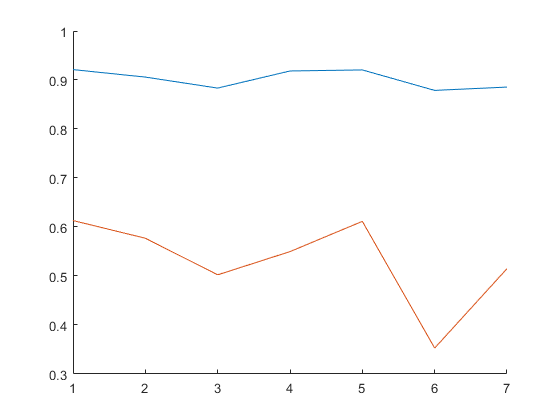

figure 
hold on
plot(VAF1)
plot(VAF)
hold off

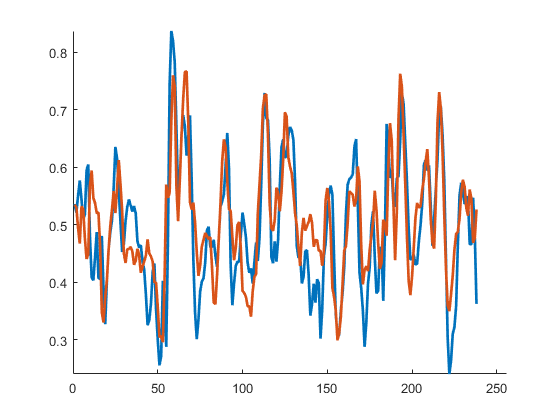


figure
hold on
plot(yt(2:end-2),'linewidth',2)
plot(ysim,'linewidth',2)
hold off
axis([0 256 -inf inf])


meanOSA = mean(VAF1)

meanOSA = 0.9020

meanMSA = mean(VAF)

meanMSA = 0.5317

% 
% 
% FY = mag2db(abs(fft(simfeaturez(3:end,1))));
% FZ = mag2db(abs(fft(yt)));
% 
% % heatmap(simfeaturez)
% % imagesc(simfeaturez)
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off

VAF1(period)

ans = 0.8856

VAF(period)

ans = 0.5151